# Ejemplo de uso: wsa_psdwb

Se muestran ejemplos del uso de la función wsa_psdwb.

#### Ruta a funciones

addpath('..\');

#### Estimación de la densidad espectral de potencia de una señal sinusoidal pura

Se calcula la estimación de la densidad espectral de potencia a una señal coseno con frecuencia angular de $\frac{1}{2}$ rad/s:


$$x[n] = \frac{1}{2}cos\left(\frac{1}{2} n\right)$$


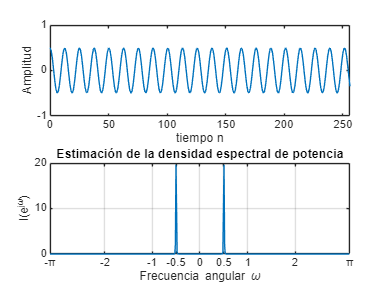

n = 0:1:2047;
x_n = 0.5*cos((1/2)*n);
[I, W] = wsa_psdwb(x_n, 512, 256, "hann");

figure;
subplot(2, 1, 1)
plot(n, x_n)
xlabel("tiempo n")
ylabel("Amplitud")
xlim([0, 256])
ylim([-1, 1])

subplot(2, 1, 2);plot(W, I); grid; title('Estimación de la densidad espectral de potencia');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('I(e^{j\omega})')

#### Estimación de la densidad espectral de potencia de una señal sinusoidal con ruido especificando la longitud de la DFT del segmento

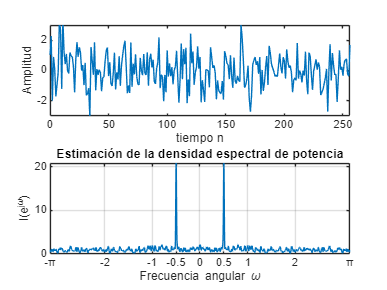

rng("default")
n = 0:1:2047;
x_n = 0.5*cos((1/2)*n) + randn(size(n));
[I, W] = wsa_psdwb(x_n, 512, 256, "hann", 'Nfft', 2048);

figure;
subplot(2, 1, 1)
plot(n, x_n)
xlabel("tiempo n")
ylabel("Amplitud")
xlim([0, 256])
ylim([-3, 3])

subplot(2, 1, 2);plot(W, I); grid; title('Estimación de la densidad espectral de potencia');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('I(e^{j\omega})')

#### Estimación de la densidad espectral de potencia de una señal sinusoidal con ruido especificando la longitud de la señal de entrada

rng default
n = 0:2047;
x_n = cos(pi/3*n)+randn(size(n));

[I, W] = wsa_psdwb(x_n, 132, 66, "hann", 'M', 462);

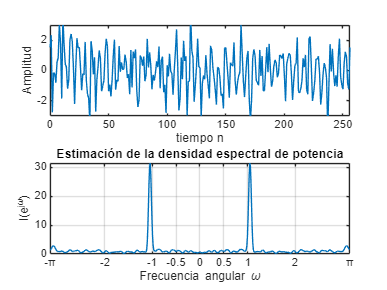


figure;
subplot(2, 1, 1)
plot(n, x_n)
xlabel("tiempo n")
ylabel("Amplitud")
xlim([0, 256])
ylim([-3, 3])

subplot(2, 1, 2);plot(W, I); grid; title('Estimación de la densidad espectral de potencia');
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel('I(e^{j\omega})')